# **TAP 1**

**Integrantes:**

- Jeffrey Antonio Monja Castro

- Angello Soldi

- Juan Carlos Paredes

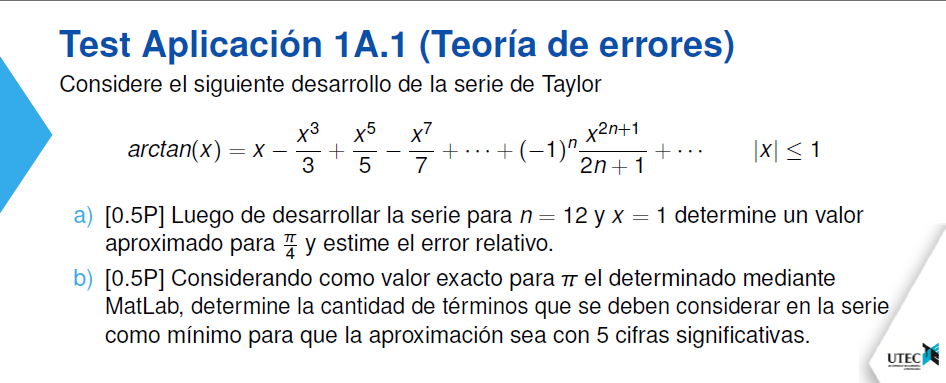

Item a)

format long

n = 12;
x = 1;

arctan_aprox = arctan_taylor_it(x, n);
arctan_exact = atan(x);

fprintf('La función arctan(x) aproximada para x = 1 y n = 12 es: %f', arctan_aprox);

La función arctan(x) aproximada para x = 1 y n = 12 es: 0.804601

fprintf('La función arctan(x) exacta para x = 1 es: %f', arctan_exact);

La función arctan(x) exacta para x = 1 es: 0.785398

x = pi/4;

arctan_aprox = arctan_taylor_it(x, n);
arctan_exacto = atan(x);
delta = abs(exacto - aprox)/abs(exacto);

fprintf('La función arctan(x) aproximada para x = pi/4 y n = 12 es: %f', arctan_aprox);

La función arctan(x) aproximada para x = pi/4 y n = 12 es: 0.665808

fprintf('El error relativo es: %f', delta);

El error relativo es: 0.000052

Item b) 

csig = 5;

terminos = arctan_taylor_nterm(x, csig);

fprintf('Nro de términos para aproximar arctan(x) es: %d', terminos);

Nro de términos para aproximar arctan(x) es: 15


% Comprobación
arctan_taylor_it(x, terminos);
atan(x);

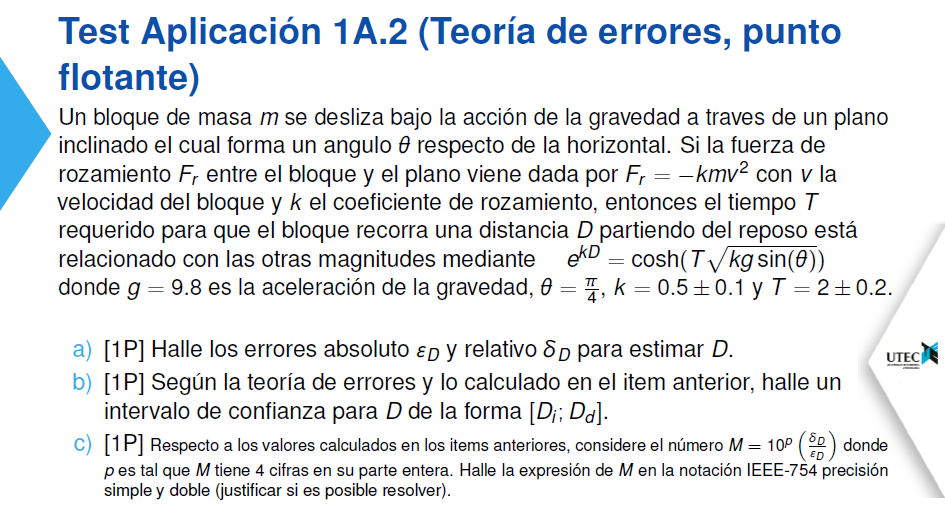

Item a)

format long
g = 9.8; 
theta = pi/4;
k1 = 0.5; error_k = 0.1;
T1 = 2; error_T = 0.2;

syms T k
D = 1/k * log(cosh(T * sqrt(k * g * sin(theta))));
D = matlabFunction(D);

dD_T = matlabFunction(diff(D,T));
dD_k = matlabFunction(diff(D,k));

delta_D = abs(dD_T(T1,k1)) * error_k + abs(dD_k(T1,k1)) * error_T;

errorabs_D = delta_D * D(T1, k1);

fprintf('Error absoluto de la función D: %f', errorabs_D);

Error absoluto de la función D: 7.931097

fprintf('Error relativo de la función D: %f', delta_D);

Error relativo de la función D: 1.308657

Item b

intervalo_inferior = D(T1, k1) - errorabs_D;
intervalo_superior = D(T1, k1) + errorabs_D;

fprintf('Intervalo de confianza para D: [%f, %f]', intervalo_inferior, intervalo_superior)

Intervalo de confianza para D: [-1.870609, 13.991584]

Item c

syms p
M = 10^p * (delta_D/errorabs_D);
M = matlabFunction(M);

n = M(4);

fprintf("El número M es: %f", n);

El número M es: 1650.032266


% IEEE-754 precisión simple
bin_simple = simple2binary(n);

fprintf("IEEE-754 simple: %s", bin_simple);

IEEE-754 simple: 01000100110011100100000100001000


% Comprobando la función inversa de binario simple a decimal
bin2dec_simple = binary2dec_simple(num2str(bin_simple));

fprintf("De IEEe-754 simple a decimal: %f", bin2dec_simple)

De IEEe-754 simple a decimal: 1650.032227


% IEEE-754 precisión doble
bin_doble = double2binary(n);

fprintf("IEEE-754 doble: %s", bin_doble);

IEEE-754 doble: 0100000010011001110010000010000100001010001111011011011100110010


% Comprobando la función inversa de binario doble a decimal
bin2dec_double = binary2dec_double(num2str(bin_doble));

fprintf("De IEEe-754 simple a decimal: %f", bin2dec_double)

De IEEe-754 simple a decimal: 1650.032266

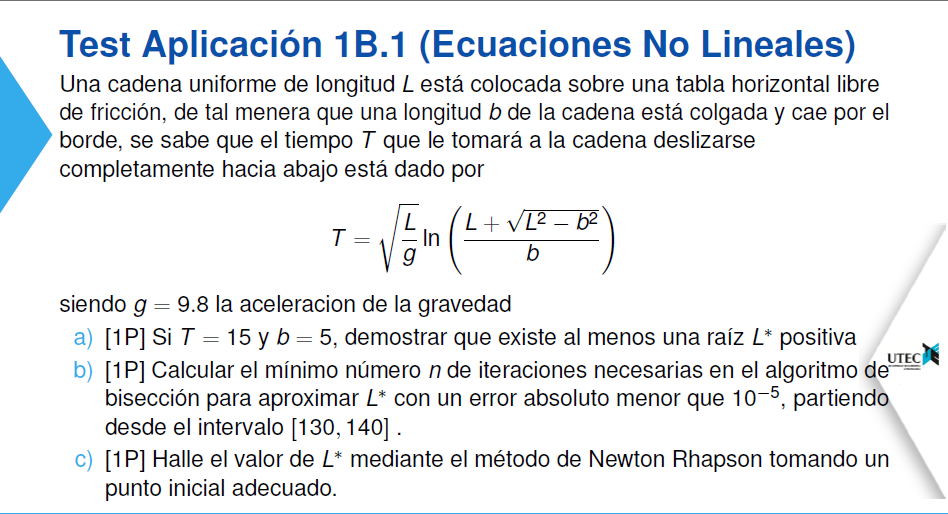

Item a)

syms L
T = 15;
b = 5;
g = 9.8;

f = sqrt(L/g) * log((L + sqrt(L^2 - b^2))/b) - T

$$f = \log\left(\frac{L}{5}+\frac{\sqrt{L^{2}-25}}{5}\right)\,\sqrt{\frac{5\,L}{49}}-15$$

f = matlabFunction(f);

% Teorema de bolzano weierstrass
if (f(0) * f(1000) < 0)
    fprintf("Existe al menos una raíz L positiva")
else 
    fprintf("No existe")
end

Existe al menos una raíz L positiva

Item b)

Tol = 10^-5;
a = 130;
b = 140;

biseccion(f, a, b, Tol)

Se necesita 19 iteraciones


ans = 1.0e+02 *

   1.300000000000000   1.400000000000000   1.350000000000000  -0.006102985392862   0.002131934839032  -0.001960098177999   0.050000000000000
   1.350000000000000   1.400000000000000   1.375000000000000  -0.001960098177999   0.002131934839032   0.000092129161369   0.025000000000000
   1.350000000000000   1.375000000000000   1.362500000000000  -0.001960098177999   0.000092129161369  -0.000932414020317   0.012500000000000
   1.362500000000000   1.375000000000000   1.368750000000000  -0.000932414020317   0.000092129161369  -0.000419752058004   0.006250000000000
   1.368750000000000   1.375000000000000   1.371875000000000  -0.000419752058004   0.000092129161369  -0.000163714134285   0.003125000000000
   1.371875000000000   1.375000000000000   1.373437500000000  -0.000163714134285   0.000092129161369  -0.000035768192651   0.001562500000000
   1.373437500000000   1.375000000000000   1.374218750000000  -0.000035768192651   0.000092129161369   0.000028186553483   0.000781250000

Item c)

newt = newton(f, 90, Tol)

newt = 1.0e+02 *

   0.900000000000000
   1.340507039832807
   1.373737455802523
   1.373874411836802
   1.373874414116109



fprintf("Valor de L aproximado con tolerancia de 10^-5: %f", newt(end))

Valor de L aproximado con tolerancia de 10^-5: 137.387441

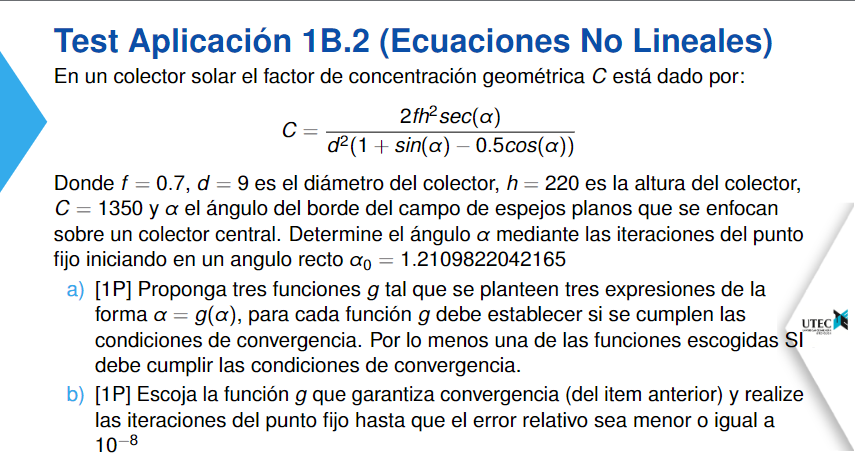

Item a)


$$\text{Primer criterio:} = |g'(x)| < 1$$



$$\text{Segundo criterio: } \forall x \in [a,b] \rightarrow g(x) \in [a,b]$$


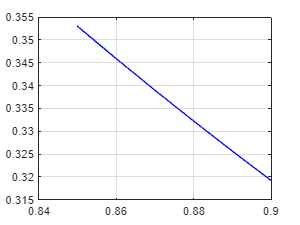

syms a

fun = (2*f*h^2*sec(a))/(d^2*(1+sin(a))-0.5*cos(a)) - C;
fun = matlabFunction(fun);

f = 0.7;
d = 9;
h = 220;
C = 1350;

% Primera función 
g1 = acos((2*f*h^2)/(C*d^2*(1+sin(a) - 0.5*cos(a))));
g1 = matlabFunction(g1);

% Primer criterio
dg1 = diff(g1(a));
dg1 = matlabFunction(dg1);

xx = 0.85:0.01:0.9;
yy = abs(dg1(xx));

plot(xx, yy, 'b');
grid on

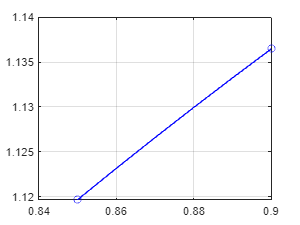


% Segundo criterio
yy = g1(xx);
plot(xx, yy, 'b', [0.85 0.9], [g1(0.85), g1(0.9)], 'ob');
grid on

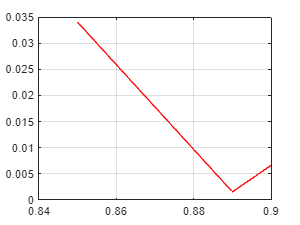



% Segunda función
g2 = asin((2*f*h^2*sin(a))/(C*d^2) + 0.5*cos(a) - 1);
g2 = matlabFunction(g2);

%% Primer criterio
dg2 = diff(g2(a));
dg2 = matlabFunction(dg2);

yy = abs(dg2(xx));

plot(xx, yy, 'r');
grid on

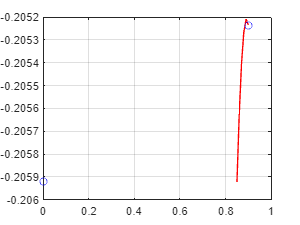


%% Segundo criterio
yy = g2(xx);
plot(xx, yy, 'r', [0 0.9], [g2(0.85), g2(0.9)], 'ob');
grid on

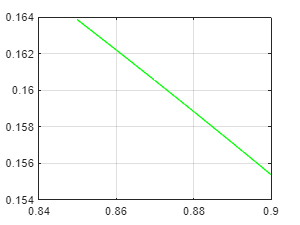



% Tercera función
g3 = acos(1/2 * (1 + sin(a) - (2*f*h^2*sin(a))/(C*d^2)));
g3 = matlabFunction(g3);

%% Primer criterio
dg3 = diff(g3(a));
dg3 = matlabFunction(dg3);

yy = abs(dg3(xx));

plot(xx, yy, 'g');
grid on

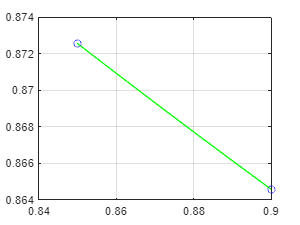


%% Segundo criterio
yy = g3(xx);
plot(xx, yy, 'g', [0.85 0.9], [g3(0.85), g3(0.9)], 'ob');
grid on

La tercera función `g3 converge para el intervalo [0.85, 0.90]`

Item b)

a0 = 1.2109822042165;
Tol = 10^-8;

sol = puntofijo(g3, a0, Tol)

sol =    1.210982204216500   1.000000000000000
   0.825769973616384   0.466488541491906
   0.876574369738097   0.057957884551077
   0.868260854115118   0.009574905494791
   0.869592020740155   0.001530794433812
   0.869378088641555   0.000246074868225
   0.869412449605991   0.000039522052452
   0.869406930158365   0.000006348520392
   0.869407816741210   0.000001019754858
   0.869407674330030   0.000000163802534


sol = sol(end, 1)

sol =    0.869407693530971



fun(sol)    

ans =     -6.133909610910104e+02



fprintf("%f", fun(sol))

-613.390961

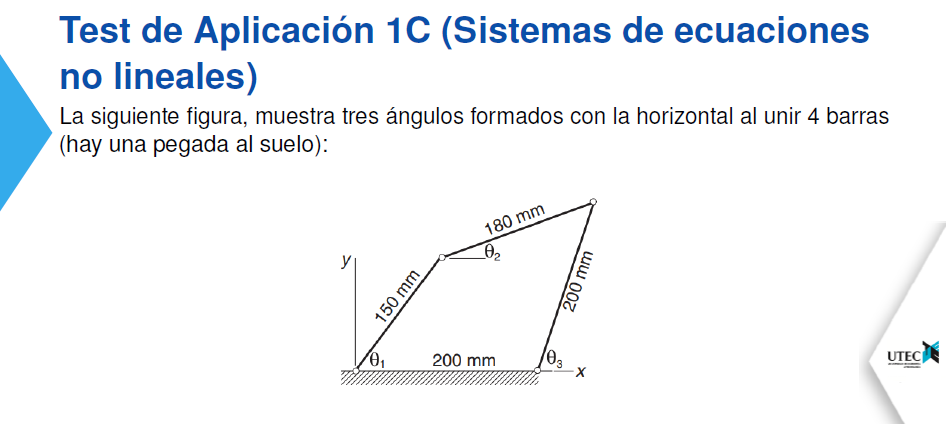

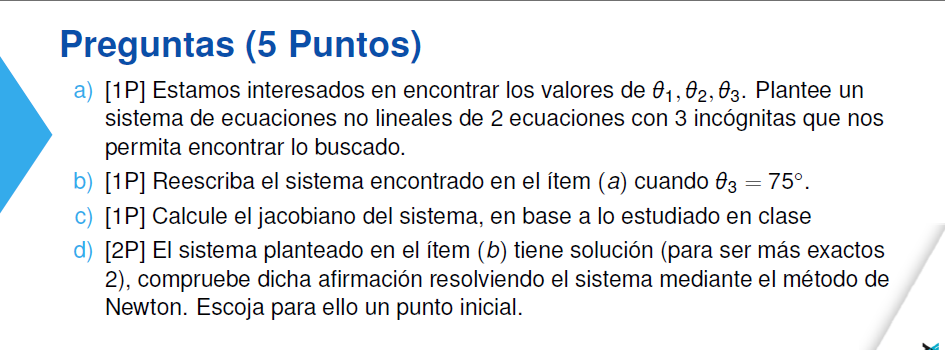

Item a)

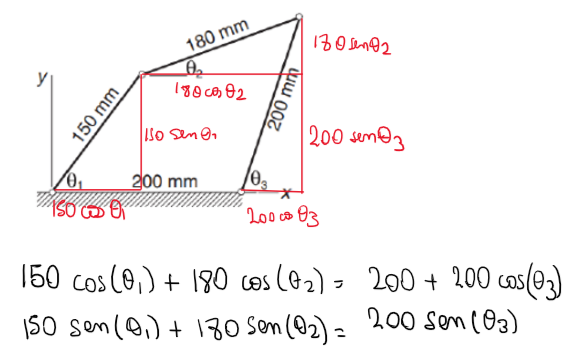

syms x y z
F = [150*cos(x) + 180*cos(y) - 200 - 200*cos(z); 150*sin(x) + 180*sin(y) - 200*sin(z)];
disp(F)

$$\left(\begin{array}{c} 150\,\cos\left(x\right)+180\,\cos\left(y\right)-200\,\cos\left(z\right)-200\\ 150\,\sin\left(x\right)+180\,\sin\left(y\right)-200\,\sin\left(z\right) \end{array}\right)$$

Item b)

z1 = deg2rad(75);
F = [150*cos(x) + 180*cos(y) - 200 - 200*cos(z1); 150*sin(x) + 180*sin(y) - 200*sin(z1)];
disp(F)

$$\left(\begin{array}{c} 150\,\cos\left(x\right)+180\,\cos\left(y\right)-\frac{35432606140316225}{140737488355328}\\ 150\,\sin\left(x\right)+180\,\sin\left(y\right)-\frac{849637342059177}{4398046511104} \end{array}\right)$$

F = matlabFunction(F);

Item c)

J = jacobian(A(x,y),[x,y]);
disp(J)

$$\left(\begin{array}{cc} -150\,\sin\left(x\right) & -180\,\sin\left(y\right)\\ 150\,\cos\left(x\right) & 180\,\cos\left(y\right) \end{array}\right)$$

Item d)

tol = 1e-3;

%Punto 1
% se elije (0,2) porque es un número que está en el intervalo que proporciona ángulos indicados
x0 = [0;2];
z1 = newtonraphson(F,x0,tol);
sol1 = [z1(end,1) z1(end,2)];
fprintf("Solución 1:\ntheta_1 = %f, theta_2 = %f", rad2deg(sol1))

Solución 1:
theta_1 = 20.018783, theta_2 = 51.996899


%Punto 2
x0 = [1;0];
z2 = newtonraphson(F,x0,tol);
sol2 = [z2(end,1) z2(end,2)];
fprintf("Solución 1:\ntheta_1 = %f, theta_2 = %f", rad2deg(sol2))

Solución 1:
theta_1 = 54.981221, theta_2 = 23.003098

Ambos puntos proporcionan respuestas que son menores a 180° sexagesimales, cumpliendo la regla de la suma interna de ángulos de los triángulos

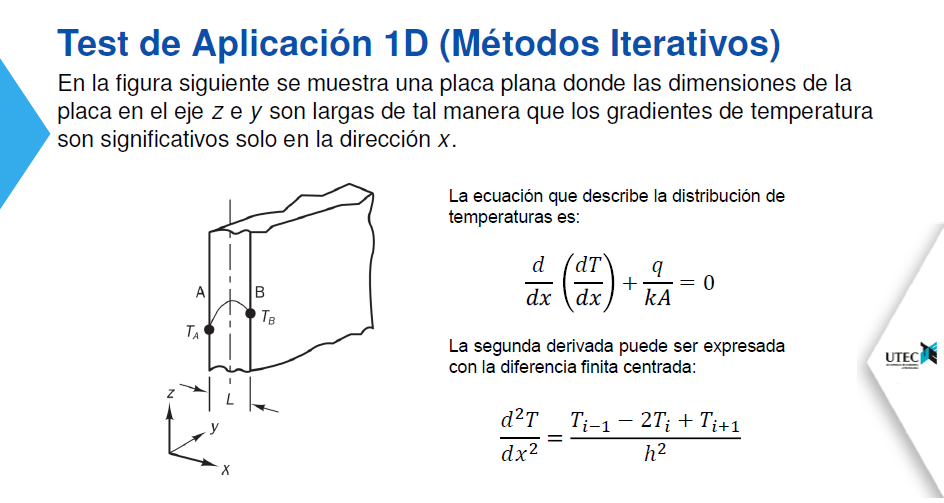

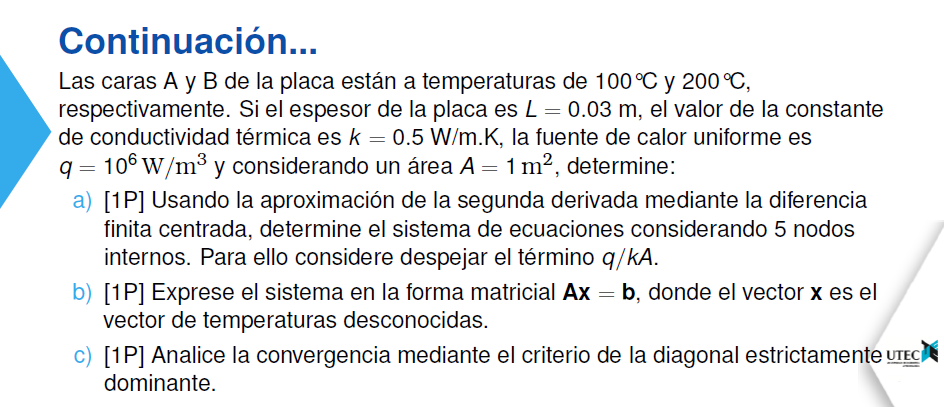

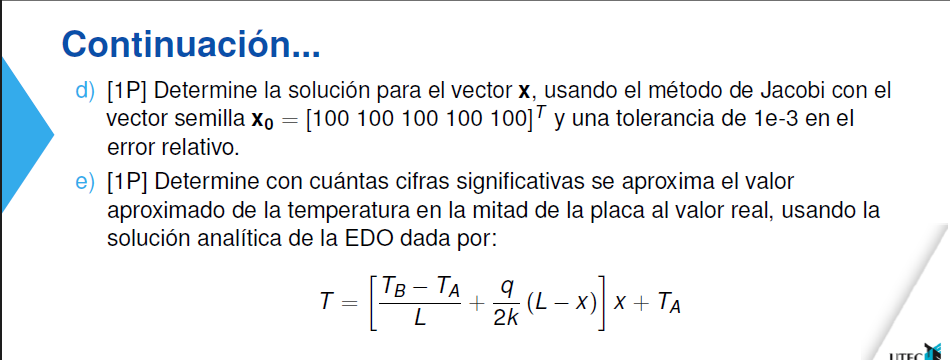

Item a)

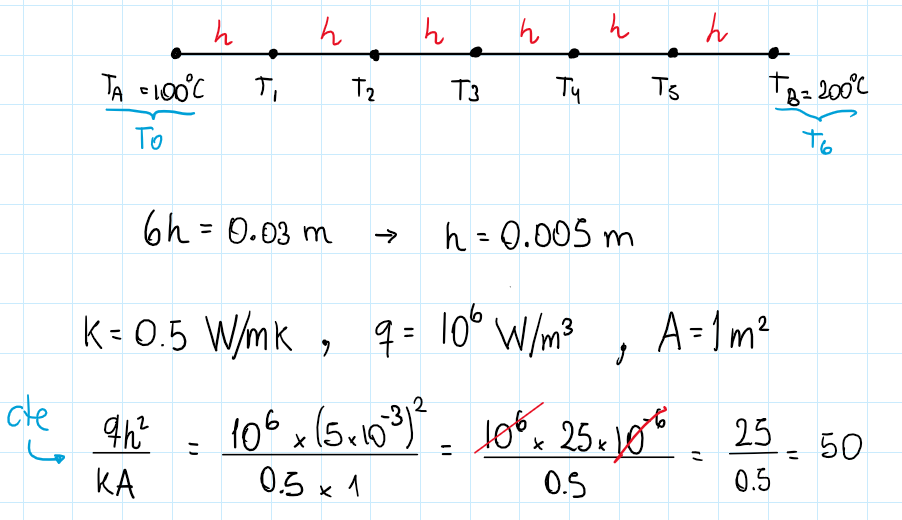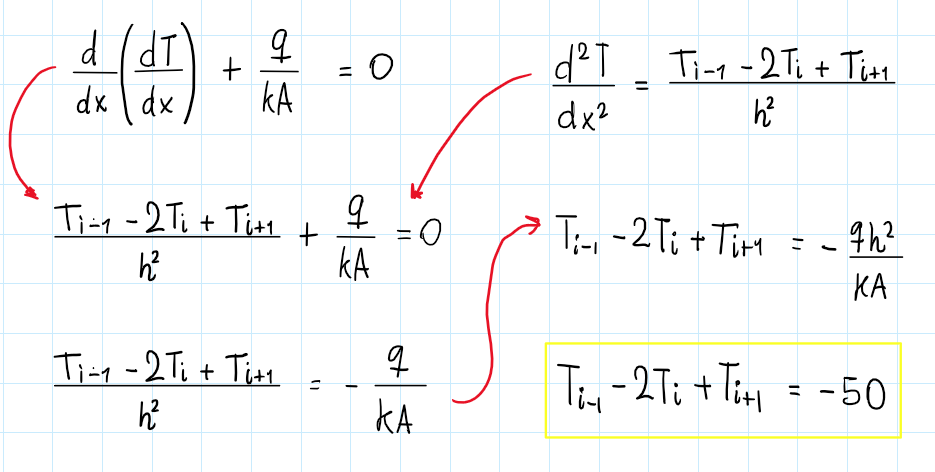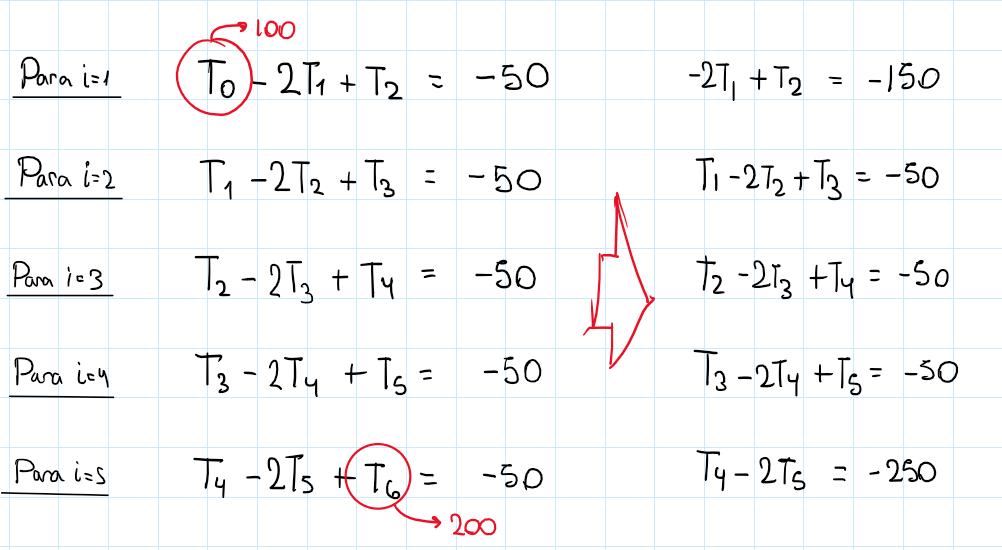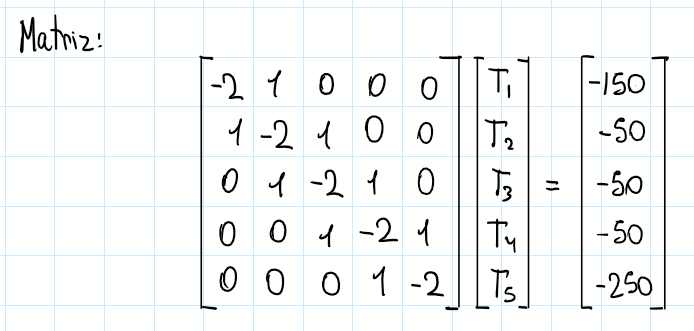

L = 0.03; k = 0.5; A = 1; q = 10^6;
h = L/6;

cte = q*h^2/k*A;

Item b)

A = [-2 1 0 0 0
     1 -2 1 0 0
     0 1 -2 1 0
     0 0 1 -2 1
     0 0 0 1 -2];
b = [-150 -50 -50 -50 -250]';

fprintf("Matriz A\n")

Matriz A


disp(A)

    -2     1     0     0     0
     1    -2     1     0     0
     0     1    -2     1     0
     0     0     1    -2     1
     0     0     0     1    -2




fprintf("Matriz b\n")

Matriz b


disp(b)

  -150
   -50
   -50
   -50
  -250



Item c)

if (~diagdom(A))
    fprintf("La matriz converge")
else
    fprintf("No se puede afirmar nada")
end

No se puede afirmar nada

Item d)

x0 = [100 100 100 100 100]';
Tol = 1e-3;

z = jacobi(A, b, x0, Tol)

z = 1.0e+02 *

   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   0.010000000000000
   1.250000000000000   1.250000000000000   1.250000000000000   1.250000000000000   1.750000000000000   0.002765256714693
   1.375000000000000   1.500000000000000   1.500000000000000   1.750000000000000   1.875000000000000   0.001666707992851
   1.500000000000000   1.687500000000000   1.875000000000000   1.937500000000000   2.125000000000000   0.001270598044499
   1.593750000000000   1.937500000000000   2.062500000000000   2.250000000000000   2.218750000000000   0.000977066145188
   1.718750000000000   2.078125000000000   2.343750000000000   2.390625000000000   2.375000000000000   0.000791480007426
   1.789062500000000   2.281250000000000   2.484375000000000   2.609375000000000   2.445312500000000   0.000633753207834
   1.890625000000000   2.386718750000000   2.695312500000000   2.714843750000000   2.554687500000000   0.000528224927855
   1.943359375000


fprintf("T1 = %f\nT2 = %f\nT3 = %f\nT4 = %f\nT5 = %f\n", z(end, 1:5))

T1 = 240.413842
T2 = 331.078249
T3 = 372.494351
T4 = 364.411583
T5 = 307.080509


Item e)

syms x
Ta = 100; Tb = 200;
T = ((Tb - Ta)/L + (q/(2*k))*(L-x))*x + Ta

$$T = 100-x\,\left(1000000\,x-\frac{100000}{3}\right)$$

T = matlabFunction(T);

X = 0.005:0.005:0.025;

fprintf("T1 = %f\nT2 = %f\nT3 = %f\nT4 = %f\nT5 = %f\n", T(X))

T1 = 241.666667
T2 = 333.333333
T3 = 375.000000
T4 = 366.666667
T5 = 308.333333



% CS

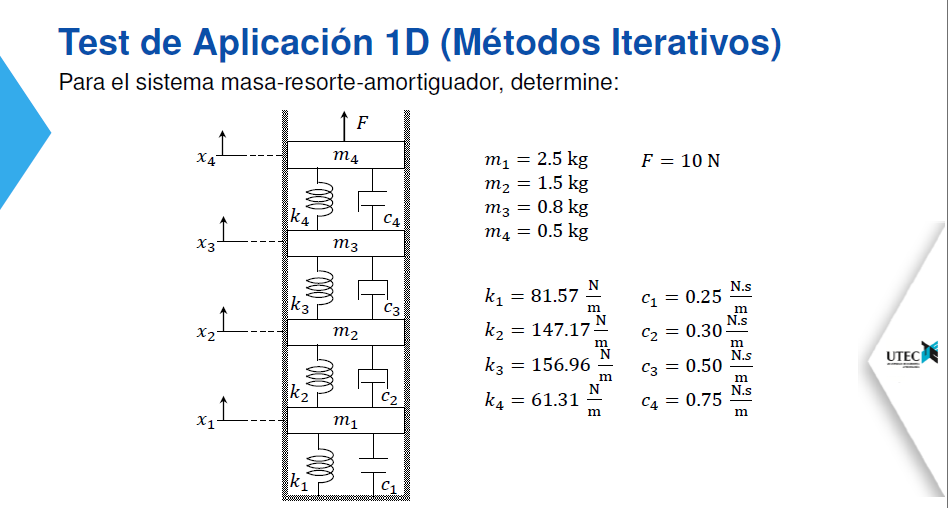

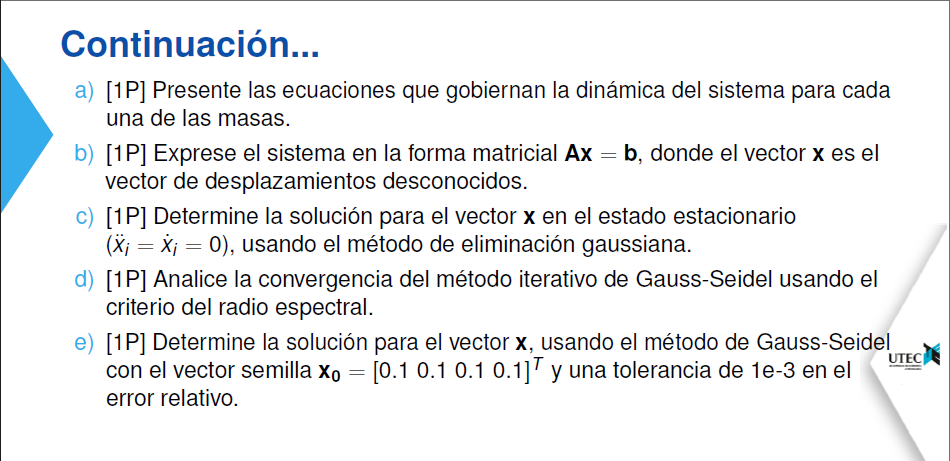

Juan Carlos

%codes

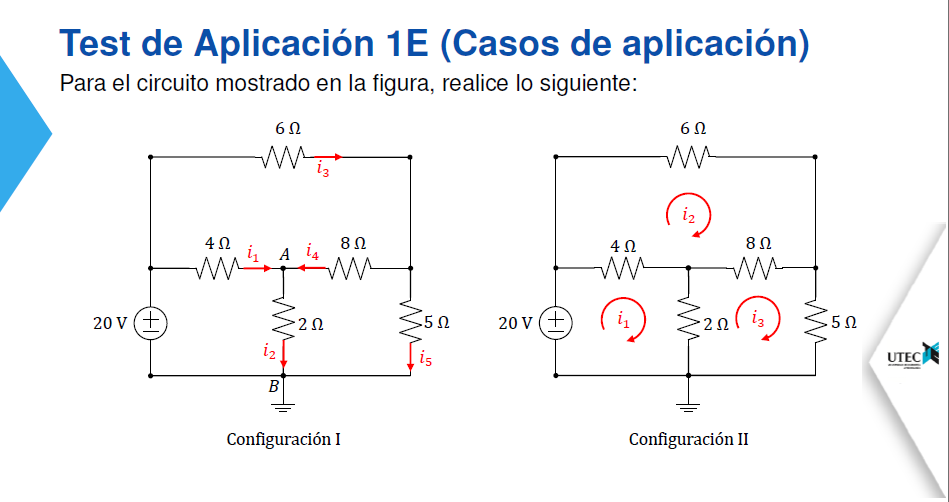

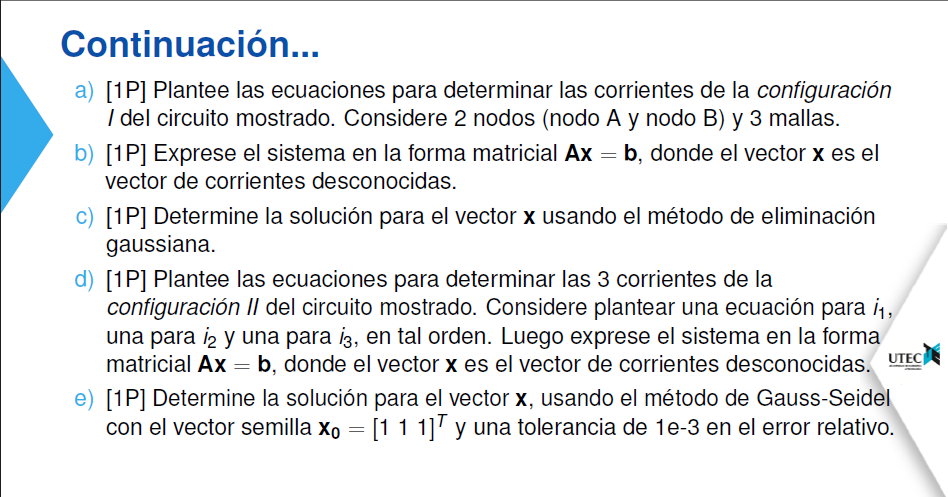

Juan Carlos

%codes


# Funciones

1A.1. Función arctan(x) con la aproximación de Taylor

function sol = arctan_taylor_it(x, n)
    sol = 0;

    for i = 0:n
        sol = sol + (-1)^i * (x^(2*i + 1))/(2*i + 1);
    end
end

1A.1. Función para hallar la cantidad de términos necesarios para ciertas cifras significativas

function sol = arctan_taylor_nterm(x, n)
    nterm = 0;
    anterior = arctan_taylor_it(x, nterm);
    delta = 1;

    while (delta > 5 * 10^-n)   
        nterm = nterm + 1;
        actual = arctan_taylor_it(x, nterm);
        delta = abs(actual - anterior)/abs(actual);
        anterior = actual;
    end

    sol = nterm + 1;
end

1A.2. Función para calcular binario IEEE-754 precisión simple

function x = simple2binary(n)
    % Signo
    if n < 0 
        sign = "1";
    else
        sign = "0";
    end

    % Extraer la parte entera
    entero = floor(n);

    bin_ent = num2str(dec2bin(entero));

    % Extraer la parte decimal    
    b = mod(n, 10);
    bin_dec = "";
    
    for i = 1: 24 - length(bin_ent)
        if b < 1
            b = b * 2;
        else
            b = b - 1;
            b = b * 2;
        end
   
        bin_dec = bin_dec + num2str(floor(b));
    end

    % Mantiza
    mantiza = bin_ent(2:end) + bin_dec;

    % Exponente
    exp = 127 + length(bin_ent(2:end));
    exp = num2str(dec2bin(exp));

    % Unión
    x = sign + exp + mantiza;
end

1A.2. Función para calcular binario IEEE-754 precisión doble

function x = double2binary(n)
    % Signo
    if n < 0 
        sign = "1";
    else
        sign = "0";
    end

    % Extraer la parte entera
    entero = floor(n);

    bin_ent = num2str(dec2bin(entero));

    % Extraer la parte decimal    
    b = mod(n, 10);
    bin_dec = "";
    
    for i = 1: 53 - length(bin_ent)
        if b < 1
            b = b * 2;
        else
            b = b - 1;
            b = b * 2;
        end
   
        bin_dec = bin_dec + num2str(floor(b));
    end

    % Mantiza
    mantiza = bin_ent(2:end) + bin_dec;

    % Exponente
    exp = 1023 + length(bin_ent(2:end));
    exp = num2str(dec2bin(exp));

    % Unión
    x = sign + exp + mantiza;
end

1A.2. Función para convertir de binario IEEE - 754 presición simple a decimal

function x = binary2dec_simple(b)
    s = b(1);
    e = b(2:9);
    m = b(10:32);

    dec_s = bin2dec(s);
    dec_e = bin2dec(e);
    dec_m = bin2dec(m)*2^(-length(m));
    x = (-1)^dec_s*2^(dec_e-127)*(1+dec_m);
end

1A.2. Función para convertir de binario IEEE - 754 presición doble a decimal

function x = binary2dec_double(b)
    s = b(1);
    e = b(2:12);
    m = b(13:64);

    dec_s = bin2dec(s);
    dec_e = bin2dec(e);
    dec_m = bin2dec(m)*2^(-length(m));
    x = (-1)^dec_s*2^(dec_e-1023)*(1+dec_m);
end

1B.1. Bisección con Tolerancia

function z = biseccion(f,a,b,Tol)
    c = (a+b)/2;
    error = (b-a)/2;
    z = [a b c f(a) f(b) f(c) error];
    N = ceil(log((b-a)/(2*Tol))/log(2));

    fprintf('Se necesita %d iteraciones\n', N)
    
    while error>Tol
        if f(a)*f(c)<0
            b = c;
        else
            a = c;
        end
        
        c = (a+b)/2;
        error = (b-a)/2;
        z = [z; a b c f(a) f(b) f(c) error];
    end

end

1B.1. Newton con tolerancia

function z = newton(f,x0,Tol)
    syms x
    df = diff(f(x));
    dfu = matlabFunction(df);
    z = x0;
    error = 1;

    while error > Tol
        x1 = x0 - f(x0)/dfu(x0);
        z = [z;x1];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end

1B.2. Punto Fijo con tolerancia

function z = puntofijo(g, x0, tol)
    error = 1;
    z = [x0 error];

    while error > tol
        x1 = g(x0);
        error = abs(x1 - x0)/abs(x1);
        z = [z; x1 error];
        x0 = x1;
    end
end

1C. Función de Newton Raphson

function z = newtonraphson(F, x0, Tol)
    syms x y
    dF = jacobian(F(x,y),[x,y]);
    df_fun = matlabFunction(dF);
    error=1;
    z = [x0' error];

    while error>Tol
        x1 = x0 - inv(df_fun(x0(1),x0(2))) * F(x0(1),x0(2));
        error = norm(x1 - x0, "inf")/norm(x1, "inf");
        z = [z; x1' error];
        x0 = x1;
    end
end

1D.1. Criterio de convergencia por Diagonal estrictamente Dominante

function op = diagdom(A)
    % op = 0 si es Estrictamente Dominante
    % op = 1 si no lo es


    [m,n] = size(A);
    op = 0;
    
    if m == n
        for k = 1:m
            if abs(A(k,k)) <= sum(abs(A(k,:))) - abs(A(k,k))
                op = 1;
                break;
            end
        end
    end
end

1.D1. Función de Jacobi  con tolerancia

function z = jacobi(A,b,x0,Tol)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tj = inv(D)*(L+U);
    cj = inv(D)*b;

    error = 1;

    z = [x0' error];

    while error>Tol
        x1 = Tj*x0 + cj; 
        error = norm(x1-x0, 1.5)/norm(x1, 1.5);
        z = [z; x1' error];
        x0 = x1;
    end
end